# Optimization exam

## Q1

Explain what is meant by a convex optimization problem and how to determine if an optimization problem is convex. You can use Exercise 1 connected to the lecture ”Convex optimization” as a guide for your explanation. (kursusgang 1-3?)

A **convex optimization problem** is a special class of optimization problems where the objective function and the feasible set (defined by constraints) have a structure that guarantees any **local minimum is also a global minimum**. This property makes convex problems particularly tractable and efficient to solve.

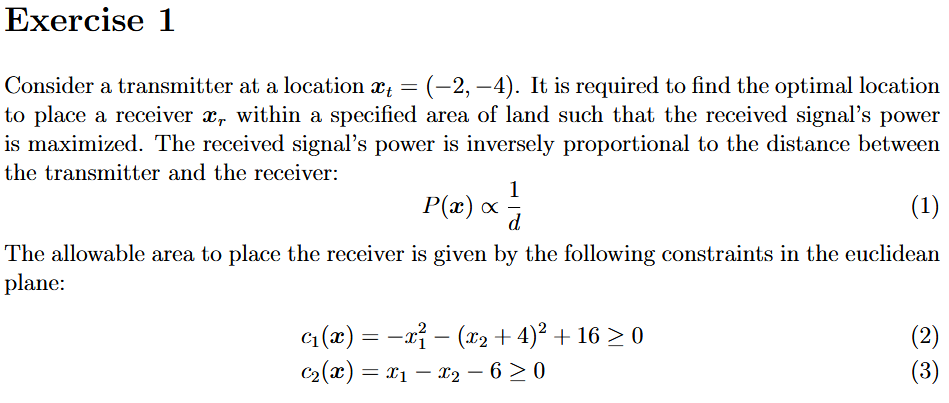

look if all constraints and loss functions are convex ie hessian positive semidefinite

syms x1 x2
f = (x1+2)^2 + (x2+4)^2;
hessian(f, [x1, x2])

$$ans = \left(\begin{array}{cc} 2 & 0\\ 0 & 2 \end{array}\right)$$


%-x1^2 - (x2+4)^2 + 16 >= 0
% ==> x1^2 + (x2+4)^2  <= 16
c1 = x1^2 + (x2+4)^2;
hessian(c1, [x1, x2])

$$ans = \left(\begin{array}{cc} 2 & 0\\ 0 & 2 \end{array}\right)$$


%x1 - x2 - 6 >= 0 
% ==>  - x1 + x2 <= 6
c2 = -x1 + x2;
hessian(c2, [x1, x2])

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

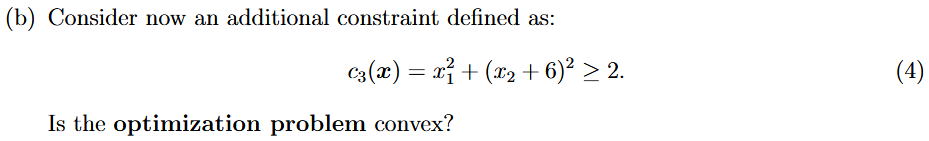

%x1^2 + (x2 + 6)^2 >= 2
%-x1^2 - (x2 + 6)^2 -2 <= 0
c3 = -x1^2 - (x2 + 6)^2 - 2;
hessian(c3, [x1, x2])

$$ans = \left(\begin{array}{cc} -2 & 0\\ 0 & -2 \end{array}\right)$$

Fra lecture 2 exercise 1

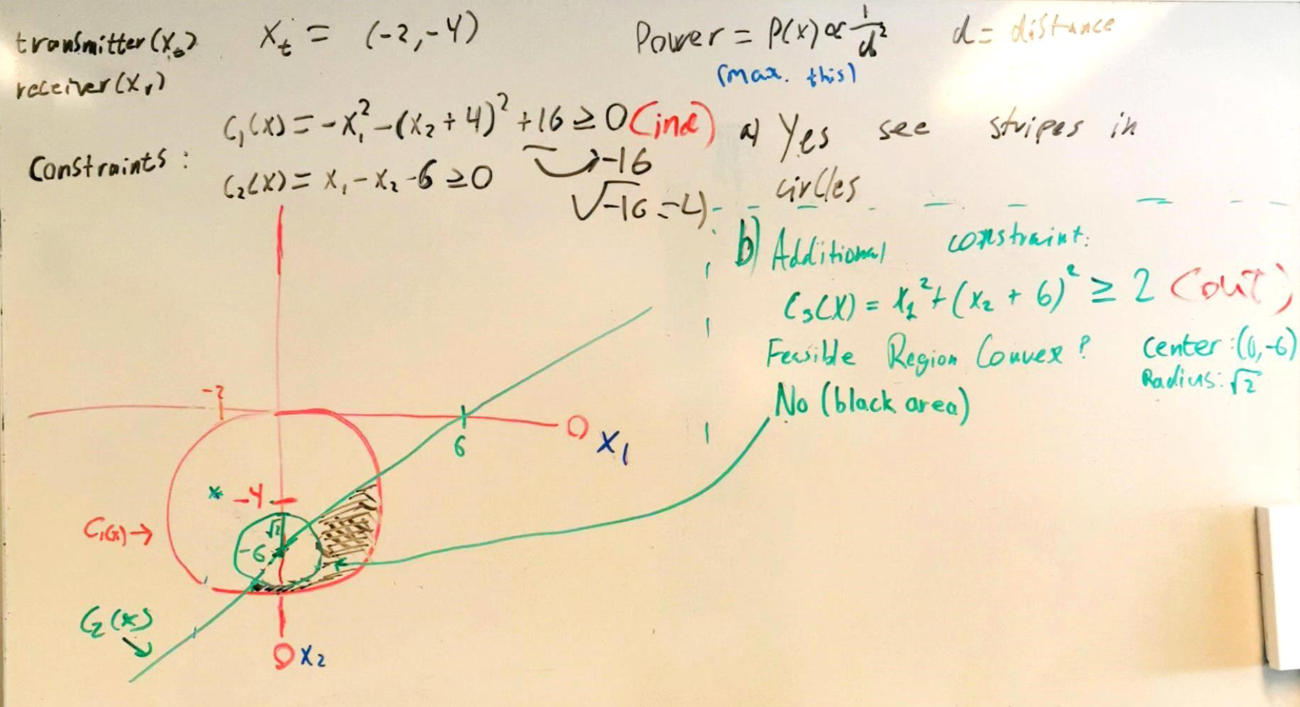

### notes for convex optimizations

- take the hessian and if it is positive semidefinite for all x in the domain it is convex

## Q2

Explain the steepest (or gradient) descent algorithm and the Newton (Raphson) algorithm. You can use Exercise 1 connected to the lecture ”Gradient methods” as a guide for your explanation.

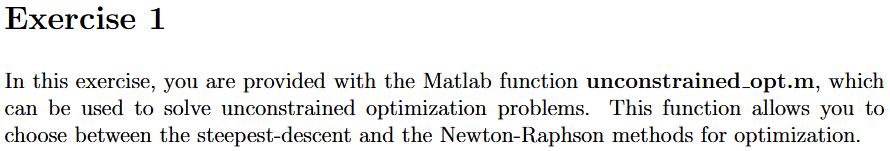

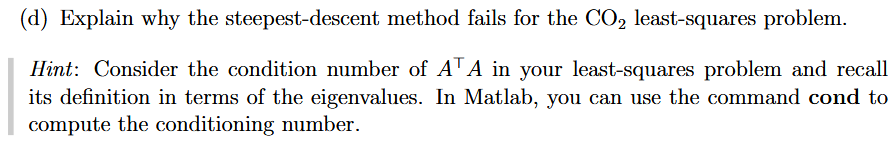

result of kappa is 7.8635e+06 is very bad beacuse much bigger than 1 leading to SD 

As a high condition number means slow convergence or instability for SD.

r is 1.2717e-07 which is very small

r is inv(kappa)

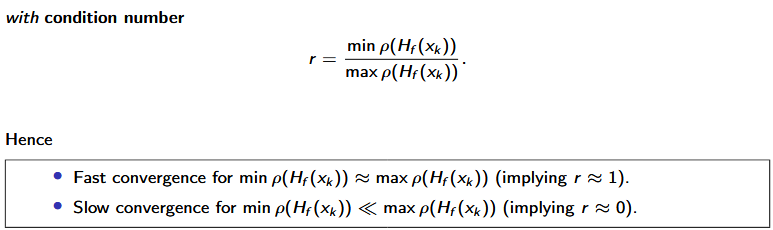from slide 14 lec 4

**What does "the Hessian tells you how fast the gradient is changing" mean?**

- **Gradient **∇f(x)\nabla f(x)**∇****f****(****x****)**** = slope or direction of steepest increase**At any point xxx, the gradient vector points in the direction where the function fff increases the fastest, and its length tells you how steep that increase is.

- **Hessian **H(x)=∇2f(x)H(x) = \nabla^2 f(x)**H****(****x****)****=****∇****2****f****(****x****)**** = the rate of change of the gradient itself**The Hessian is a matrix made of second derivatives. Each element in the Hessian measures how one component of the gradient changes as you move in a certain direction.

Example:

- Imagine you're hiking on a hill represented by the function f(x).

- The **gradient** at your current spot tells you which way is uphill and how steep that uphill is.

- The **Hessian** tells you how the steepness (the gradient) changes if you take a step in different directions.

- If the Hessian is **positive and large** in a direction, it means the hill curves **upwards sharply** in that direction — the slope will increase quickly as you move.

- If the Hessian is **close to zero** in a direction, the slope is roughly constant — the hill is more flat there.

- If the Hessian has **mixed signs** (positive and negative eigenvalues), the function curves **up in some directions and down in others** (like a saddle).

Quickie:

- Gradient = slope at a point (which way is uphill).

- Hessian = how that slope itself changes as you move around (how the hill bends).

### notes

 Gradient Descent:

 An iterative optimization method that moves in the direction of the

 negative gradient (steepest descent) of the function.

 Update rule: x_{k+1} = x_k - alpha_k * grad_f(x_k)

 - Simple and widely applicable.

 - Slower convergence, especially near the minimum.

 - Step size alpha_k must be chosen carefully.

 Newton-Raphson Method:

 Uses second-order (Hessian) information to find a stationary point

 by approximating the function locally as a quadratic.

 Update rule: x_{k+1} = x_k - inv(Hessian_f(x_k)) * grad_f(x_k)

 - Faster (quadratic) convergence near the optimum.

 - Computationally expensive due to Hessian calculation and inversion.

 - Can fail if Hessian is not positive definite.

## Q3

 Explain the Gauss-Newton method. You can use Exercise 3 connected to the lecture ”Gradient methods” as a guide for your explanation.

gauss newton for non lineaer least square


$$\underset{x}{\min \;} ||f\left(x\right)||^2 =\sum_{i=1}^3 {\left(||x-b_i ||^2 -d_i^2 \right)}^2$$


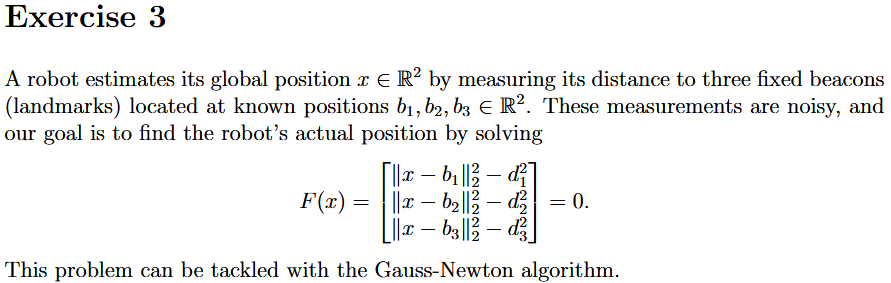

Golden Section Search (GSS) Analysis:

-------------------------------------

- GSS is used at each Gauss-Newton iteration to determine the optimal step size 

  along the direction d_k.

- The number of iterations required by GSS decreases over time:

    - Initially: 30 iterations

    - Then: 19, 6, and eventually 0 iterations

- This behavior suggests that the algorithm is approaching the minimum,

  so the initial bracketing interval isn't shrinking much — GSS terminates quickly.

- The solution x (in 2D) appears to converge to:

      x ≈ [1.0314, 1.0079]

- The final value of the cost function is:

      f(x) = 0.0061

  This small value indicates that the algorithm achieved a good fit (low residual error)

- Overall, the Gauss-Newton with GSS successfully converged within 9 iterations.

### notes

% Gauss-Newton Method:

% An iterative method for solving nonlinear least squares problems of the form:

%   min_x  (1/2) ||r(x)||^2

% where r(x) is a vector of residuals.

% Update rule:

%   x_{k+1} = x_k - (J(x_k)^T J(x_k))^(-1) J(x_k)^T r(x_k)

% where J(x_k) is the Jacobian matrix of r(x) evaluated at x_k.

% Advantages:

% - Efficient for nonlinear least squares problems.

% - Avoids computing the full Hessian matrix.

% Disadvantages:

% - Only applicable to least squares problems.

% - Can fail if J^T J is not invertible or if the residuals are highly nonlinear.

this is a least square problem and use gauss newton to solve it

## Q4

 Explain how to solve convex optimization problems using the Karush-KuhnTucker condition. You can use Exercise 1 connected to the lecture ”Constrained Optimization II” as a guide for your explanation.

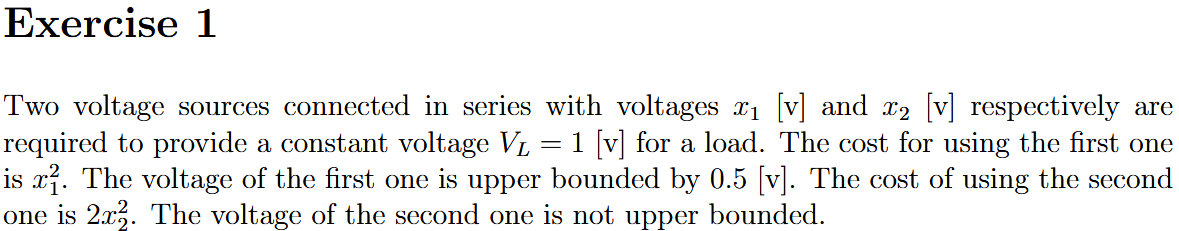

 Case 3: x1 = 0 ⇒ mu2 ≥ 0 (active), x2 = 1 from equality constraint

 Stationarity conditions:

   From ∂L/∂x1: 0 + lambda + mu1 - mu2 = 0  → (A)

   From ∂L/∂x2: 4*x2 + lambda = 0 → 4 + lambda = 0 ⇒ lambda = -4  → (B)

 Plug (B) into (A): -4 + mu1 - mu2 = 0 ⇒ mu1 = 4 + mu2 ⇒ mu1 ≥ 4

 Complementary slackness:

   x1 = 0 ⇒ mu2 ≥ 0 (OK)

   x2 = 1 > 0 ⇒ mu3 = 0

   x1 = 0 ≤ 0.5 ⇒ mu1 ≥ 0 (OK)

 All KKT conditions are satisfied.

 Cost: f = x1^2 + 2*x2^2 = 0 + 2*1^2 = 2

 Compare to Case 2 (x1 = 0.5, x2 = 0.5): f = 0.25 + 0.5 = 0.75

 ⇒ This case is feasible but not optimal (higher cost)

% Final Answers:

 (a) Optimal solution from KKT:

     x1 = 0.5, x2 = 0.5

     Lagrange multipliers: lambda = -2, mu1 = 1, mu2 = 0, mu3 = 0

 The objective function f(x1, x2) = x1^2 + 2*x2^2 is strictly convex.

 The constraints are all linear (affine): x1 + x2 = 1, x1 ≤ 0.5, x1 ≥ 0, x2 ≥ 0.

 Therefore, the entire optimization problem is convex.

If the optimization problem is convex_a then the KKT necessary conditions are

also sufficient (for a global minimizer). slide 10 lec constrained opti II

Jacobian lecture constrained II slide 12

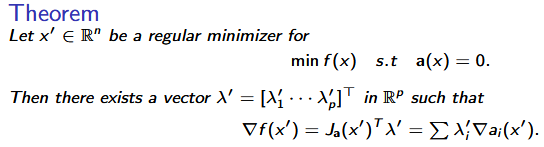

## Q5

Name a parametric method and a nonparametric method with an explanation on the major differences between them. You can use Exercise 1 connected to the lecture ”Parametric and Nonparametric Methods” as a guide to your explanation

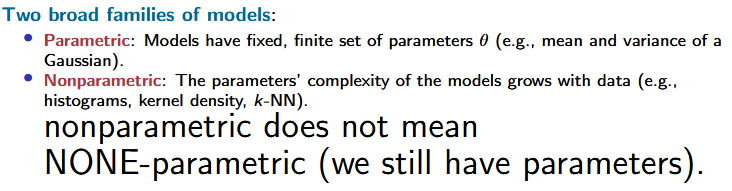

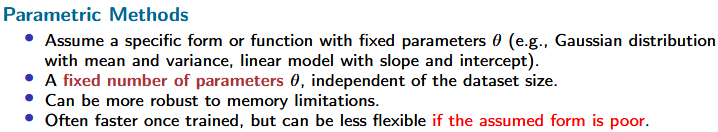

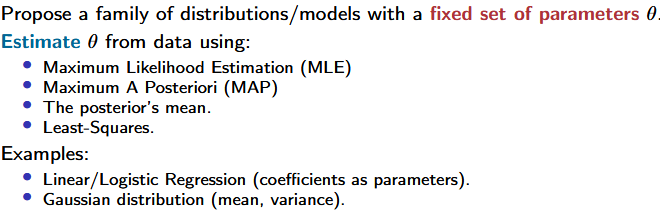

non parametric

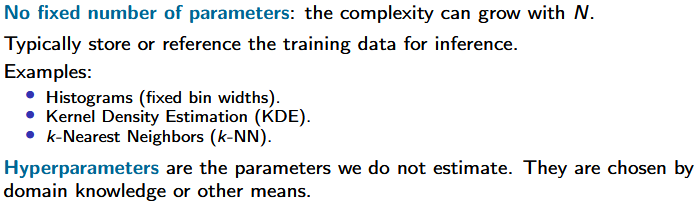

remember bayesian decision theory

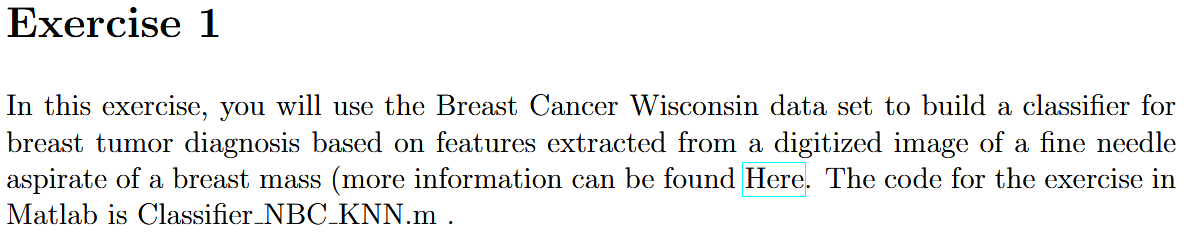

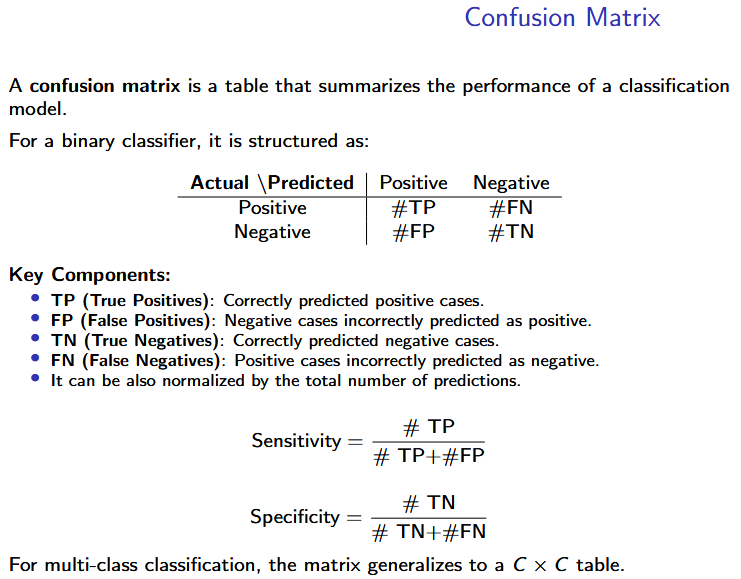

non-parametric

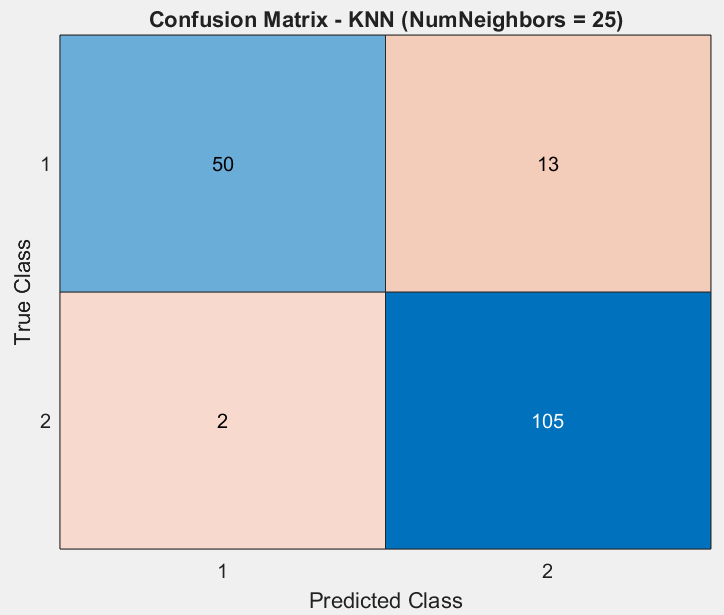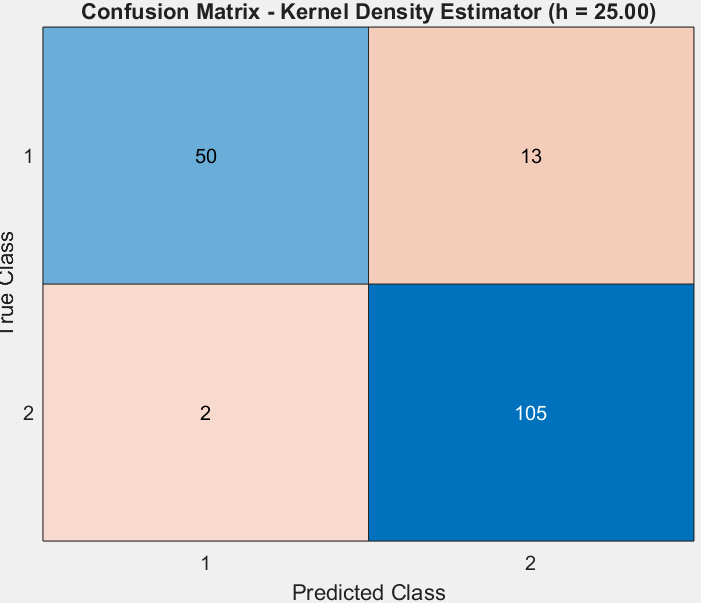

parametric

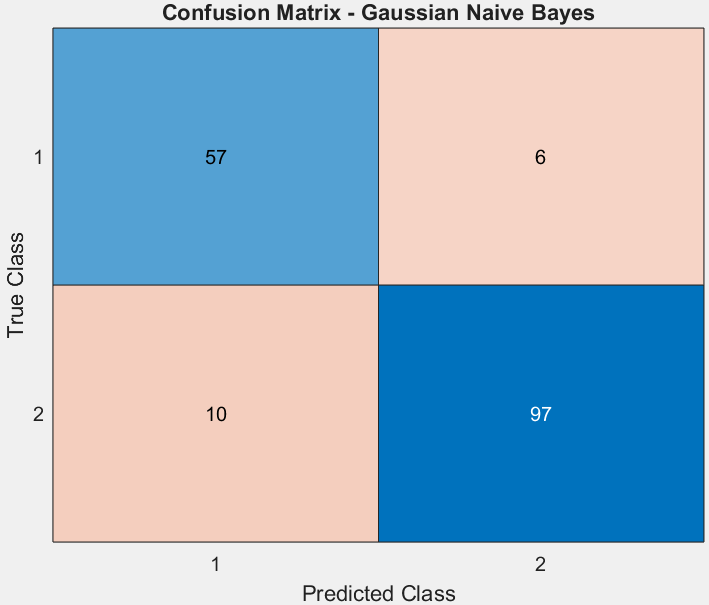

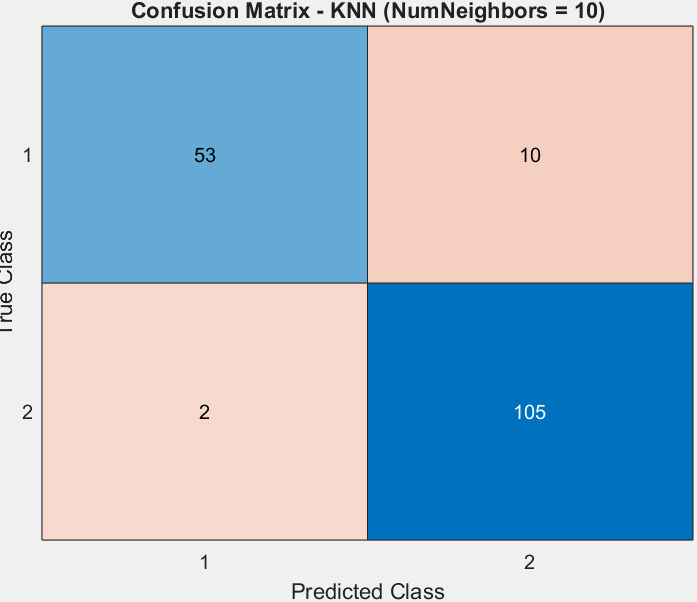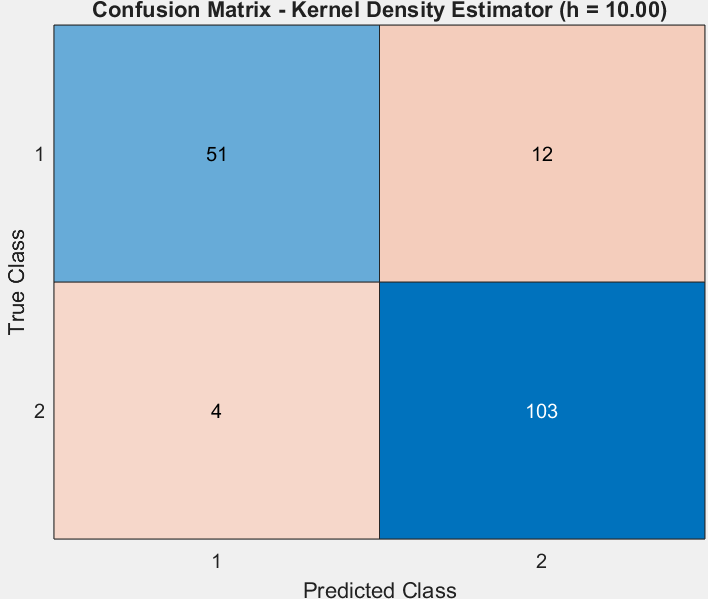

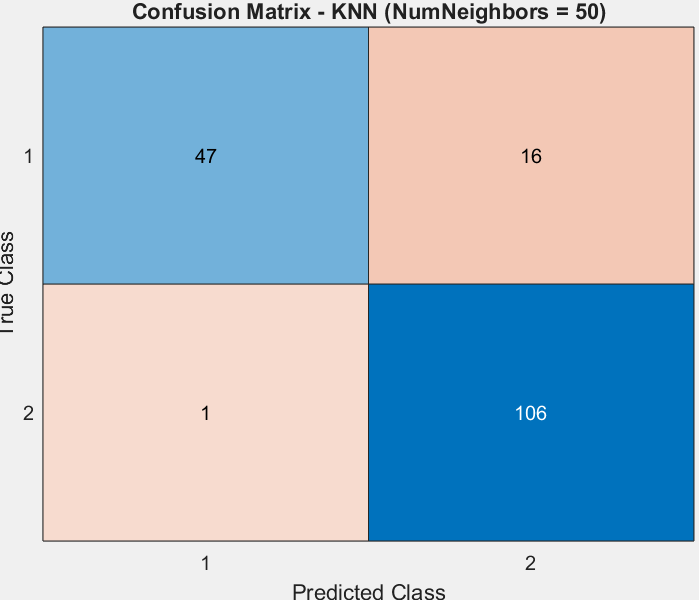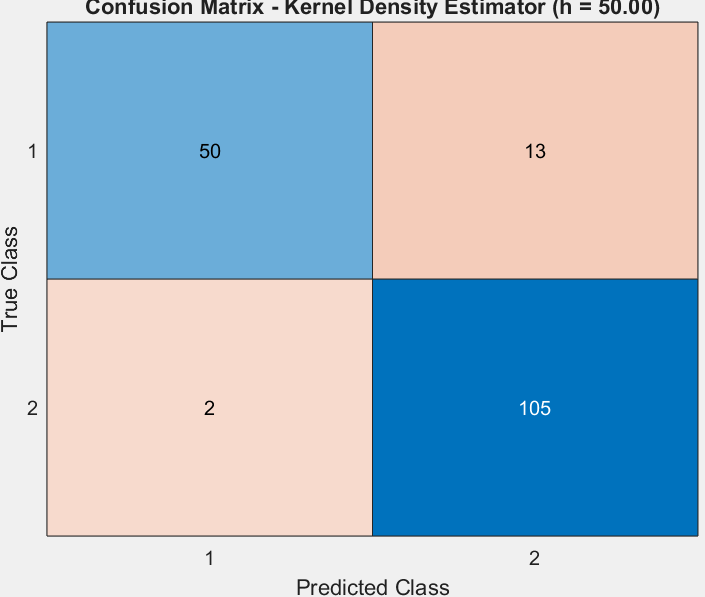

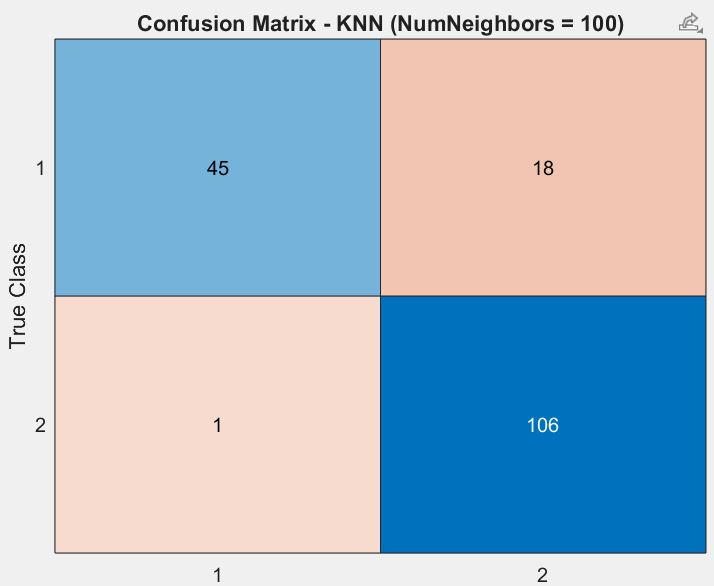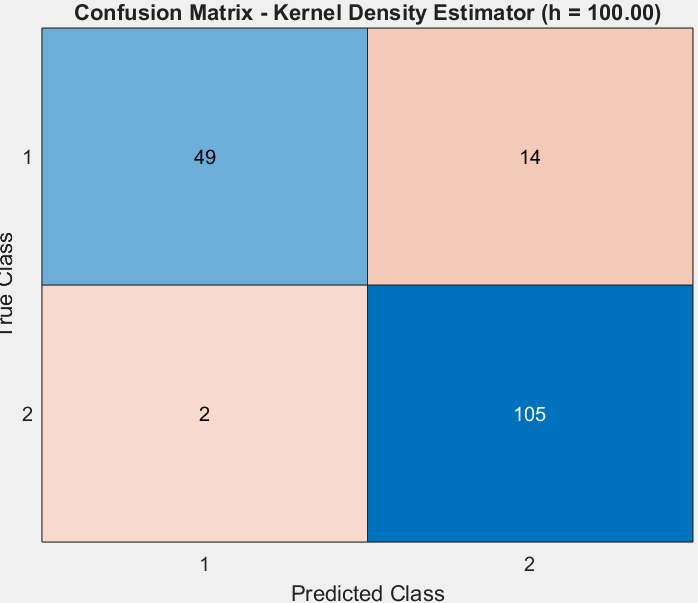

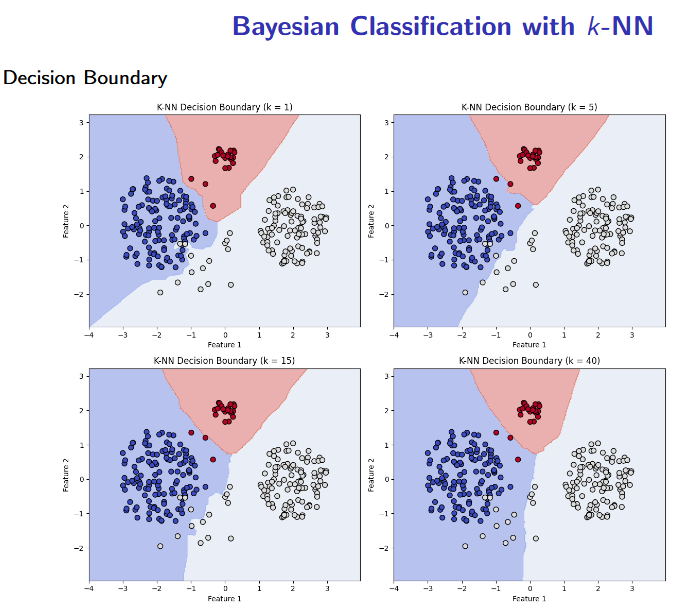

🔍**KNN (K-Nearest Neighbors):**

- **Small K (few neighbors):**

- High model complexity.

- Sensitive to noise.

- **Risk of overfitting**.

- **Large K (many neighbors):**

- Smoother, more general decisions.

- **Risk of underfitting** if K is too large.

**📈 ****KDE (Kernel Density Estimation):**

- **Small bandwidth (narrow kernel):**

- Sharp, highly localized density estimates.

- Can model fine detail, but also **prone to overfitting**.

- **Large bandwidth (wide kernel):**

- Smooths over more data.

- Can **underfit** and miss structure in the data.

### notes

## Q6

Explain the general model of linear regression with different possible regularizations. You can use Exercise 1 connected to the lecture ”Linear Regression” as a guide to your explanation.

**🔹 ****Solution Type**

- **L2 (Ridge)**: Has a **closed-form solution**—you can compute the optimal weights directly using linear algebra.

- **L1 (Lasso)**: Requires **iterative optimization** (like coordinate descent or gradient-based methods), since there's no closed-form due to the non-differentiability of the L1 norm at zero.

**🔹 ****Sparsity**

- **L2 (Ridge)**: Does **not** produce sparse coefficients; it shrinks them, but they usually stay non-zero.

- **L1 (Lasso)**: Encourages **sparsity**—some coefficients are driven exactly to **zero**, making the model simpler.

**🔹 ****Feature Selection**

- **L2 (Ridge)**: Does **not** inherently select features—it keeps all variables, just reduces their magnitudes.

- **L1 (Lasso)**: Performs **automatic feature selection** by zeroing out less important features.

**🔹 ****Robustness to Outliers**

- **L2 (Ridge)**: **Less robust** to outliers because the squared error heavily penalizes large deviations.

- **L1 (Lasso)**: **More robust** since it penalizes linearly—large errors don’t overly dominate the loss.

**🔹 ****Prior Distribution (Bayesian Perspective)**

- **L2 (Ridge)**: Assumes a **Gaussian (Normal)** prior on the coefficients—weights are likely to be small but not zero.

- **L1 (Lasso)**: Assumes a **Laplace (double exponential)** prior—stronger encouragement for some weights to be exactly zero.

🟦**Ridge Regression (L2)**

- Uses **Gaussian prior**: 

- Encourages **small**, but **non-zero** weights

- Results in **shrinkage**, not sparsity

**🟥 ****Lasso Regression (L1)**

- Uses **Laplace prior**: 

- Encourages **sparse** weights (many exactly **zero**)

- Performs **feature selection**

Why "Laplace Prior" Induces Sparsity,

The Laplace distribution has sharp peaks at 0 and heavy tails (see figure below). This means: Coefficients are biased toward zero (shrinkage). Many coefficients are exactly zero (sparsity), as the Laplace prior assigns higher probability density to zero values compared to a Gaussian prior.

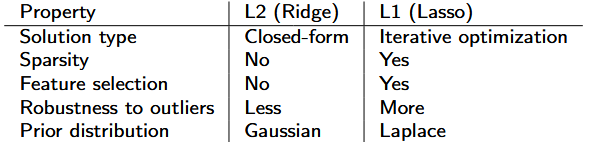

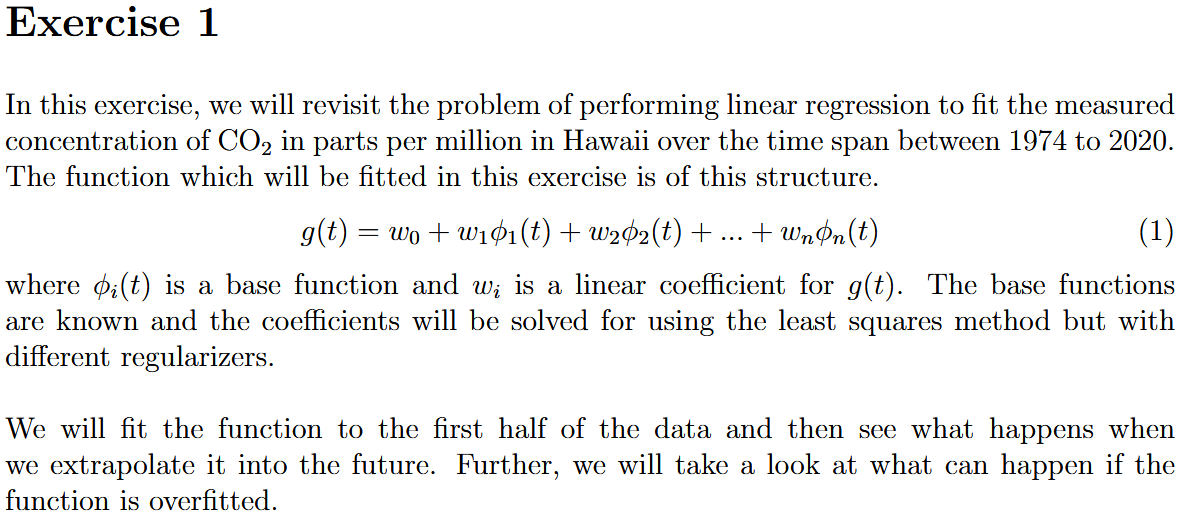

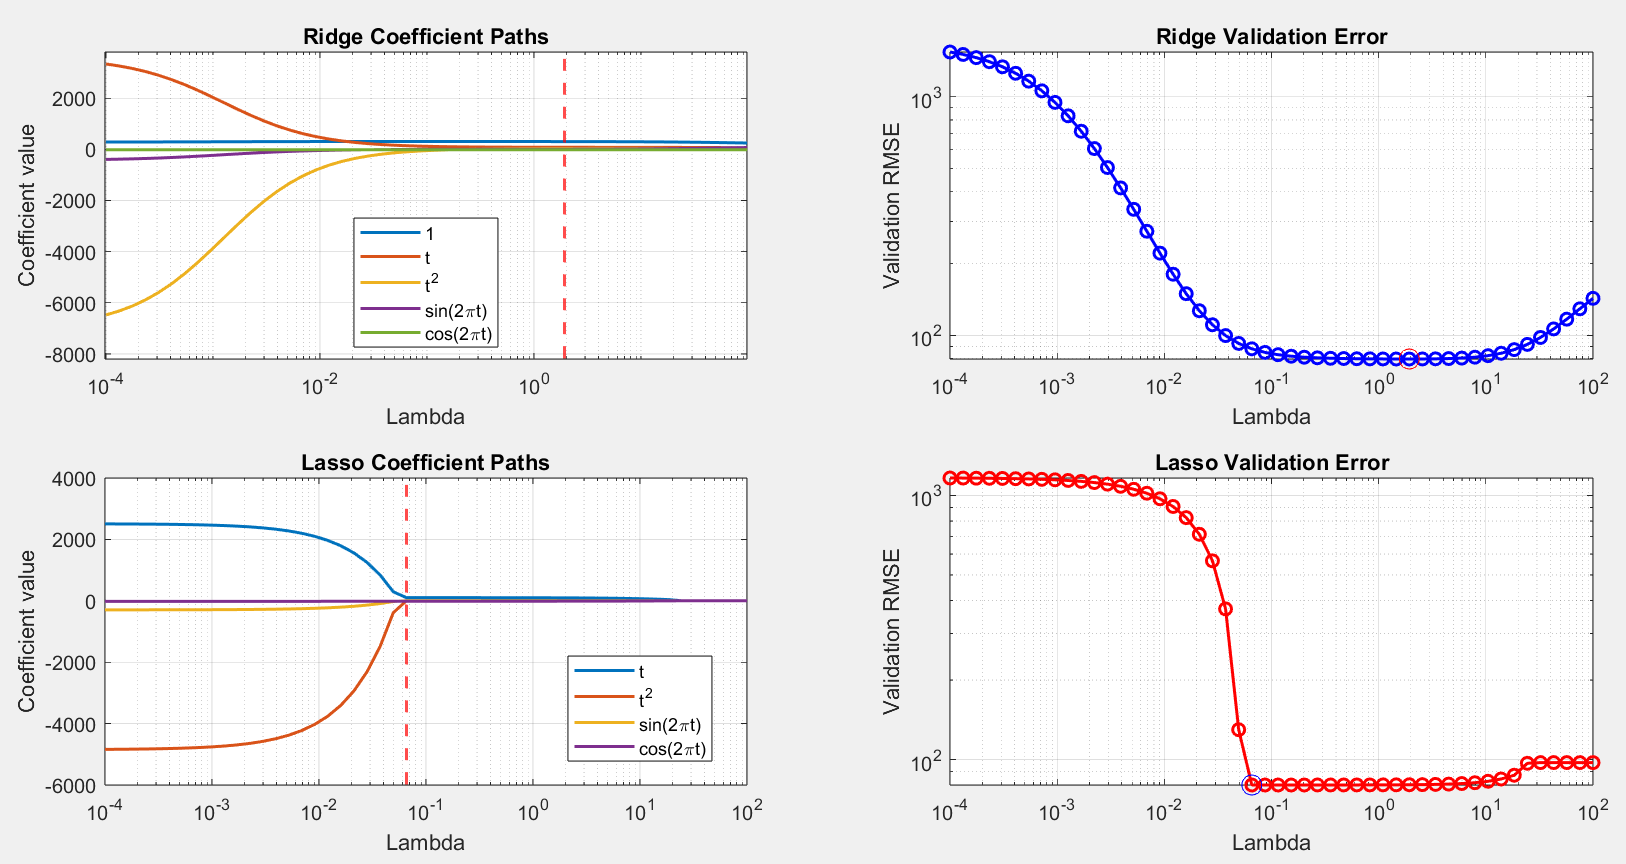

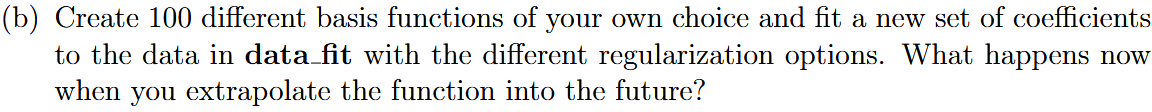

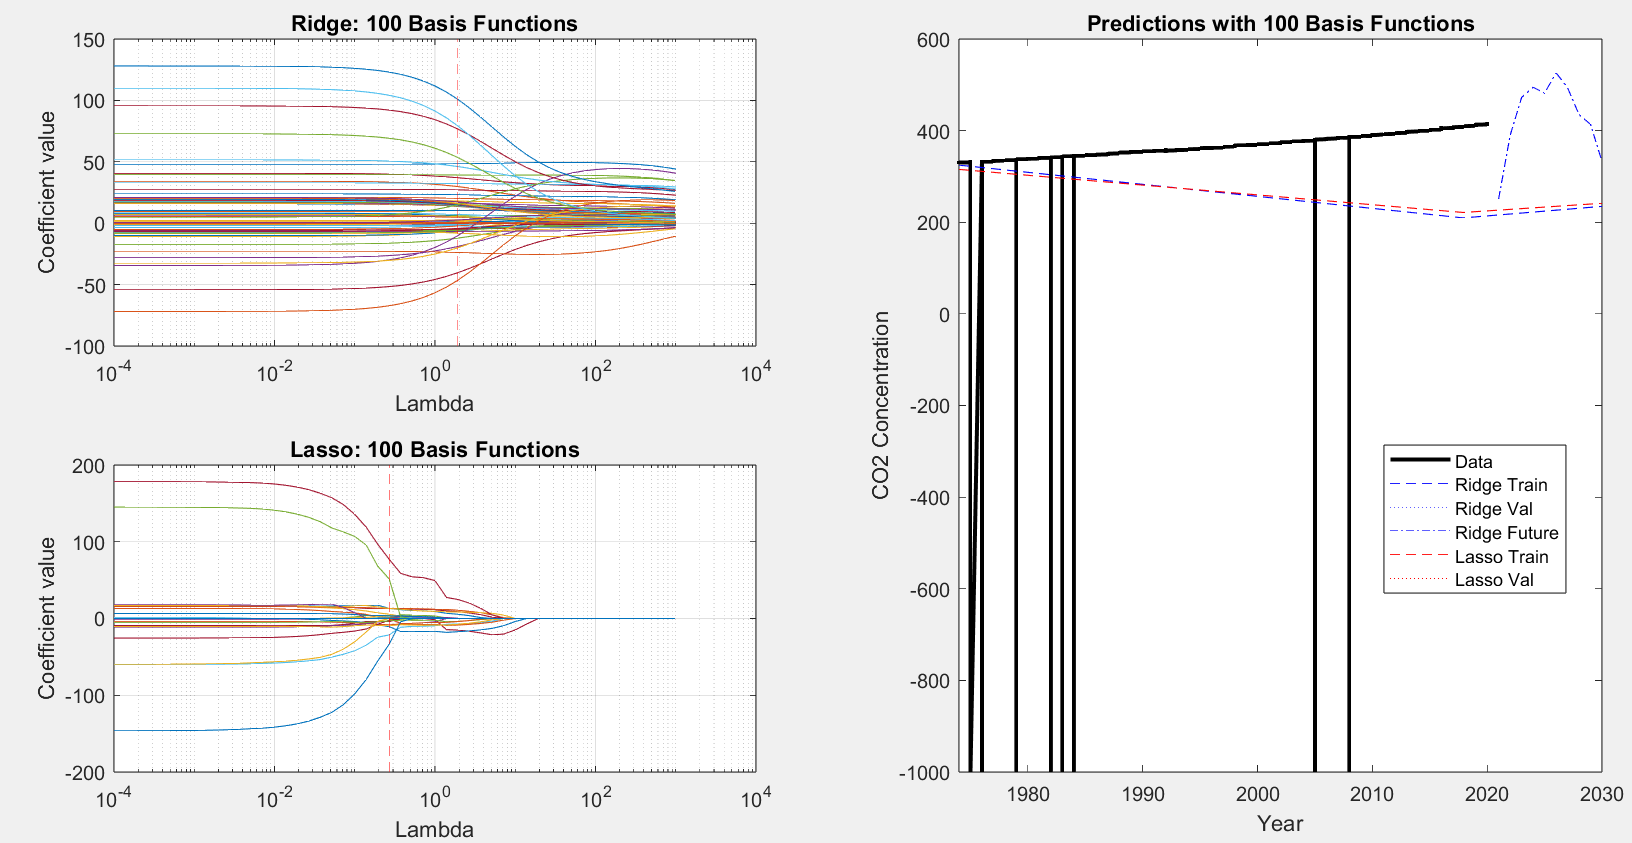

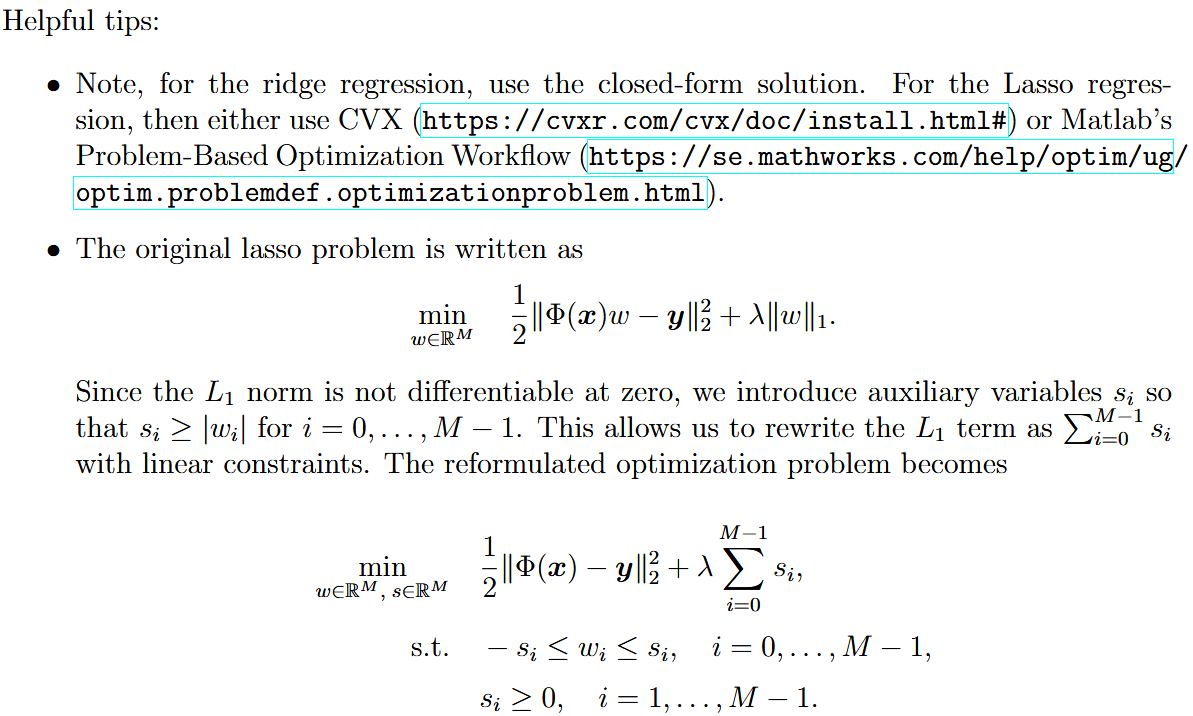

### notes

## Q7

Explain the general model of logistic regression and the importance of feature selection. You may use Exercise 1 connected to the lecture ”Linear Classification” as a guide to your explanation. 

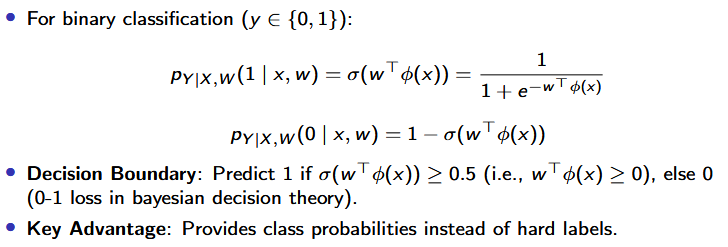slide 35 in lecture linear classification

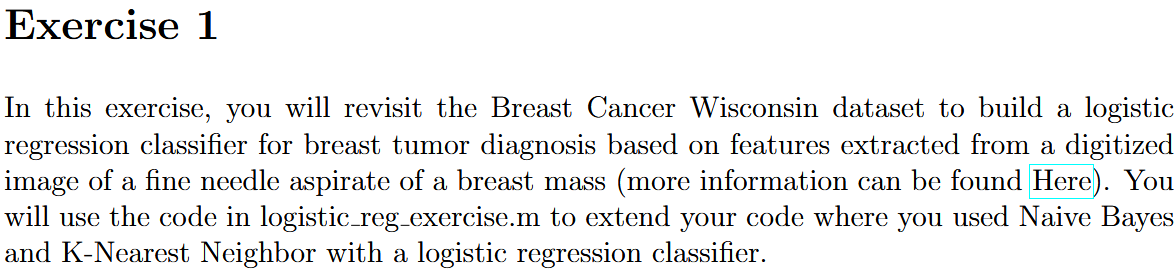

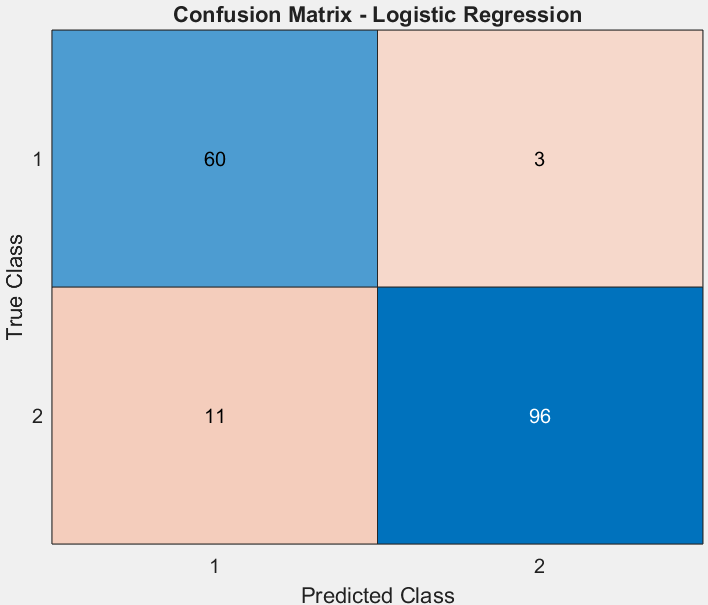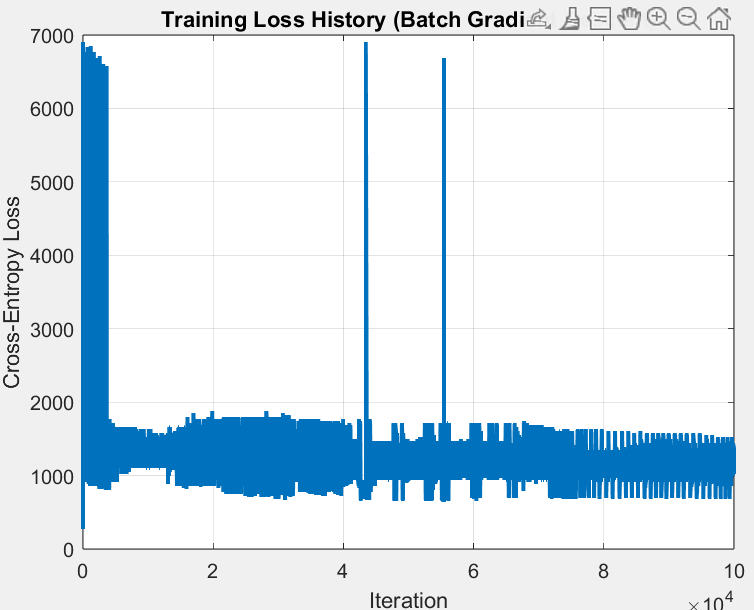

looks like gaussian naive bayes(parametric) 

compared to the others i gets more TP and FP and less FN and TN which i good in the this case with breast cancer

sumary plott 2 todo think its right

## Q8

 Explain the general model of multilayer perceptrons and their expressive power. Mention an algorithm to train them. You can use Exercise 2 from the lecture connected to ”Introduction to Neural Networks” as a guide to your explanation. 

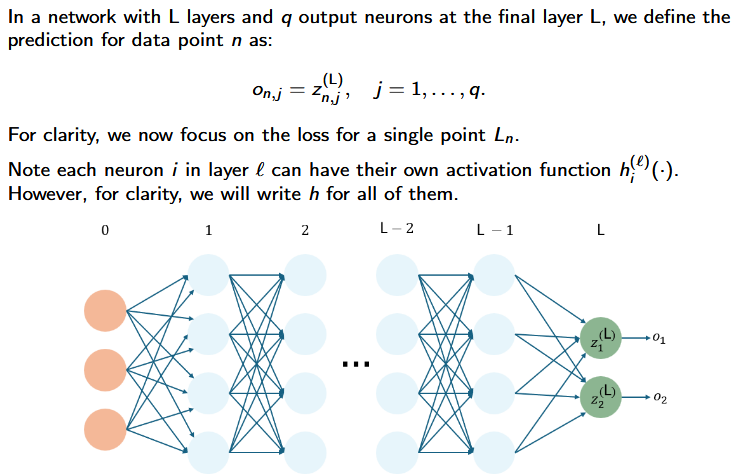

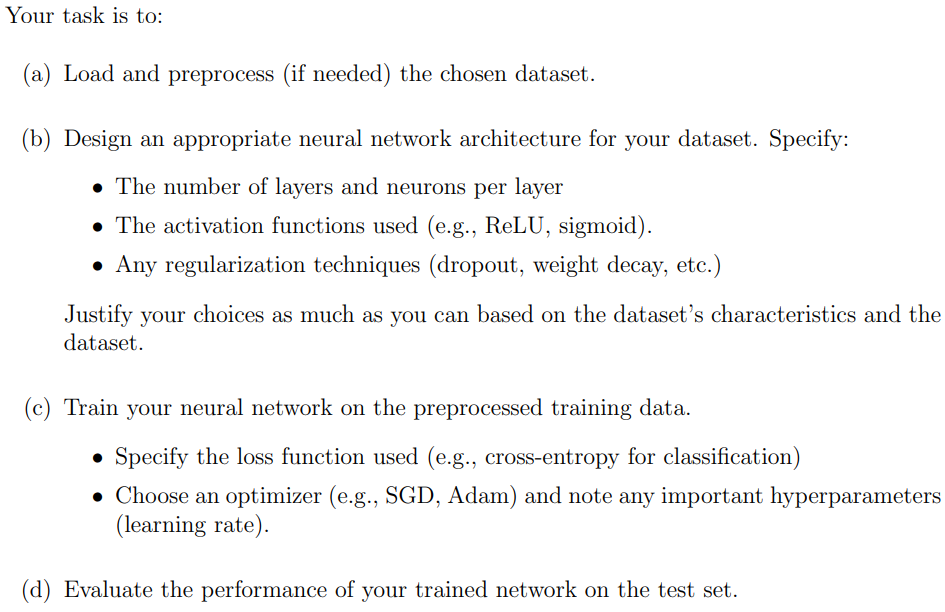

look at john code on github :)

2 layer hidden and output

answer from the scwipt

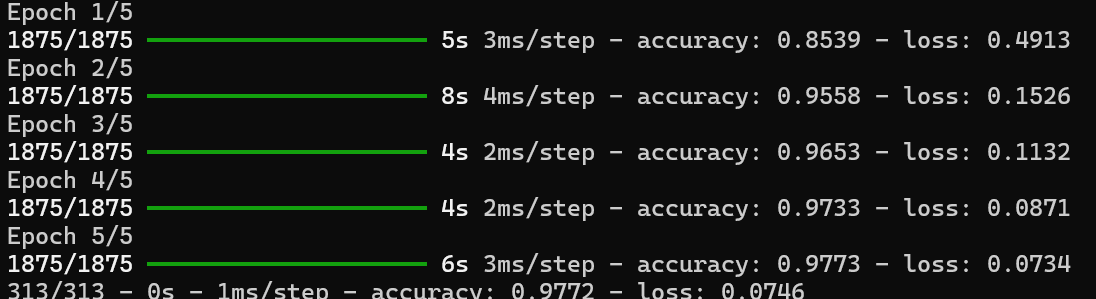

## Q9

 Explain the general concept of Principal Component Analysis (PCA) and how it can be computed using the Singular Value Decomposition (SVD). You can use Exercise 1 connected to the lecture ”PCA and SVD” as a guide to your explanation.

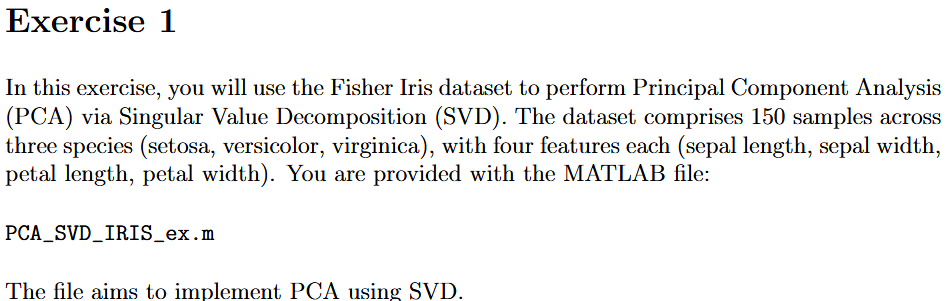

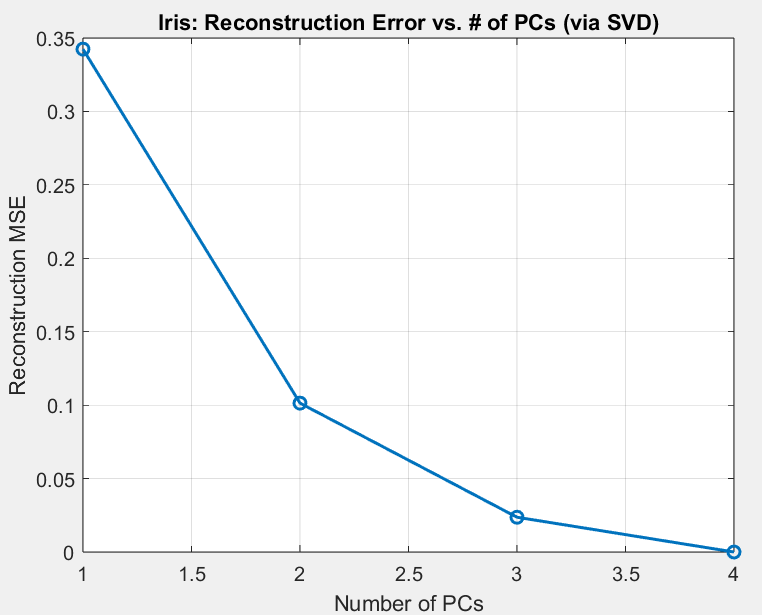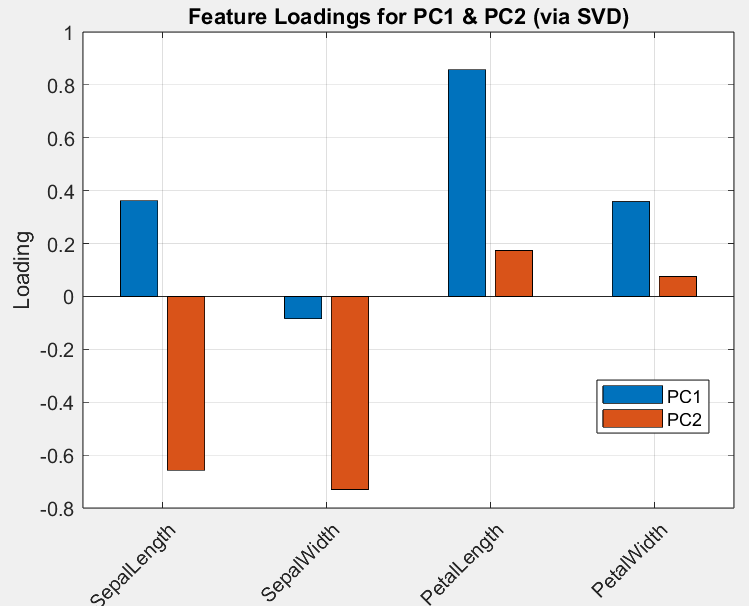

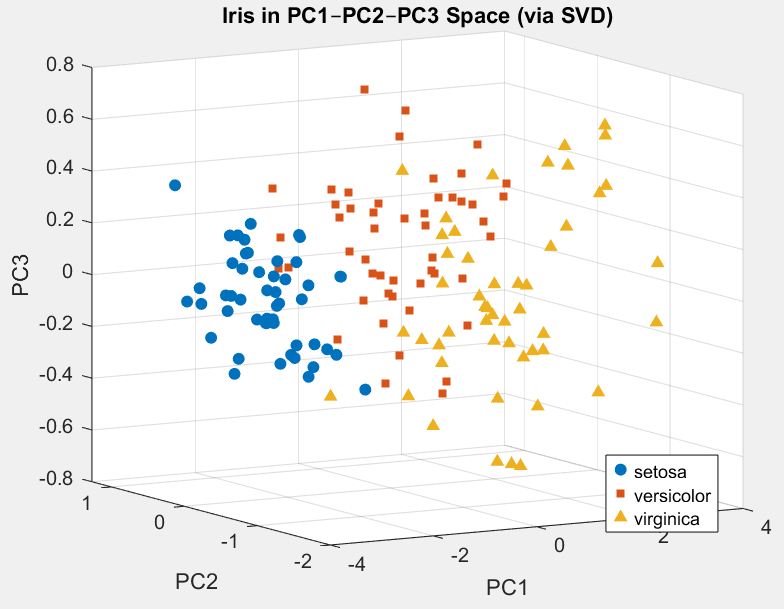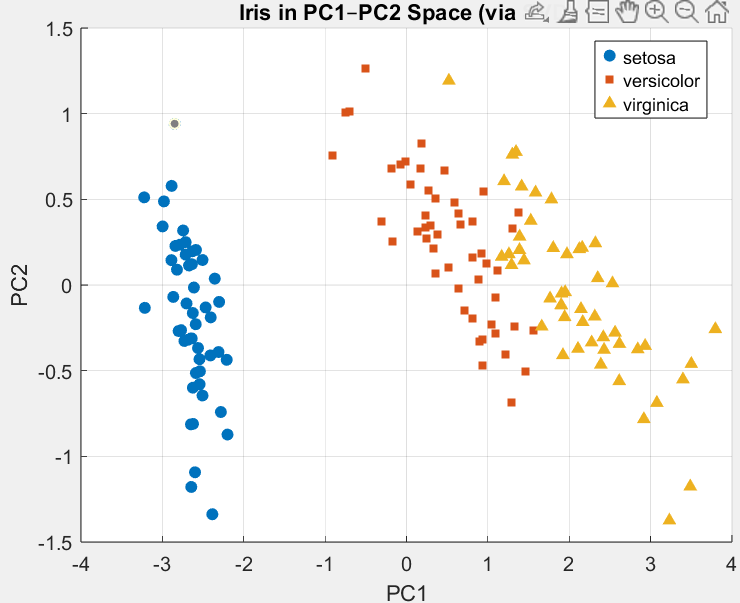

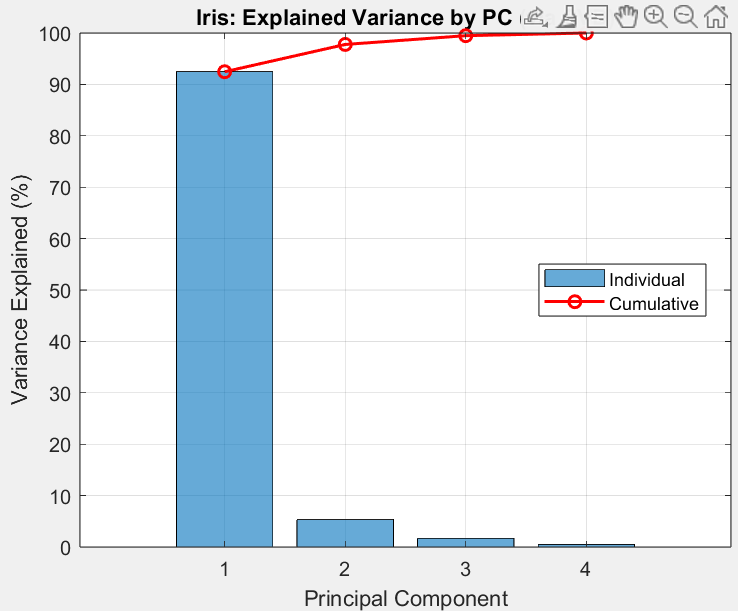

**🧩 1. ****Reconstruction Error and Feature Loadings****Left plot: *****Reconstruction Error vs. Number of PCs***

- This shows that using **only 1 PC**, the reconstruction MSE is high (~0.35).

- With **2 PCs**, error drops substantially.

- By **3 PCs**, the reconstruction is already very accurate, and by 4 it's nearly perfect.

➡️ **Interpretation**: The data can be represented with high accuracy using just **2–3 principal components** — a big dimensionality reduction from 4 features.

**Right plot: *****Feature Loadings for PC1 & PC2***

- **PC1** is dominated by **PetalLength (strong positive)** and **SepalWidth (negative)**.

- **PC2** shows high negative loading on **SepalWidth** and positive loading on **SepalLength** and **PetalWidth**.

➡️ **Interpretation**: The most important variance in the data is largely explained by **PetalLength** and **SepalWidth** — these are the key features driving PC1 and PC2.

**📊 2. Data in PC Space****Left plot: *****3D Scatter Plot in PC1–PC2–PC3 Space***

- Each color/shape represents a class (Setosa, Versicolor, Virginica).

- **Setosa** is clearly separated from the other two in PC space.

- **Versicolor** and **Virginica** are more overlapping, though still separable.

**Right plot: *****2D Scatter Plot in PC1–PC2***

- Again, **Setosa** is linearly separable.

- **Versicolor vs Virginica** have some overlap, but PC1 does a decent job separating them.

➡️ **Interpretation**: The **first two PCs** capture the most class-distinguishing information. PCA helps **visualize and possibly cluster** the data.

**📈 3. Explained Variance Plot**

- **PC1** alone explains over **90%** of the variance.

- **PC2** adds about 6–7%.

- After PC2, each additional PC adds very little (< 2%).

➡️ **Interpretation**: Almost all the structure in the data can be explained by **just PC1 and PC2**, which aligns with the sharp drop in reconstruction error and the scatter plots.

**🧠 Overall Conclusion**

- **Dimensionality reduction** from 4D to 2D is highly effective for Iris.

- **PC1 is dominant**, largely reflecting petal length and sepal width.

- PCA enables both **efficient compression** and **clear visualization**.

- **Setosa is easy to separate**, while Versicolor and Virginica require more nuanced decision boundaries (as seen in PC2/PC3).